% using a plain old .m so git can see changes
clear all
close all

%% set parameters

recordingName = "2frame_attract"; dcOffset = -0.1330;lowPulse = -0.7527 - dcOffset;
% recordingName = "2frame_mystery";
% recordingName = "2frame_n64logo";
% recordingName = "manyframe_mystery";

%% import data

load("scope recordings\" + recordingName + ".mat")

% fix scaling
v = (v-dcOffset)/lowPulse*(-0.286);

% calculate signal specs
N = length(t);
T = mean(diff(t));

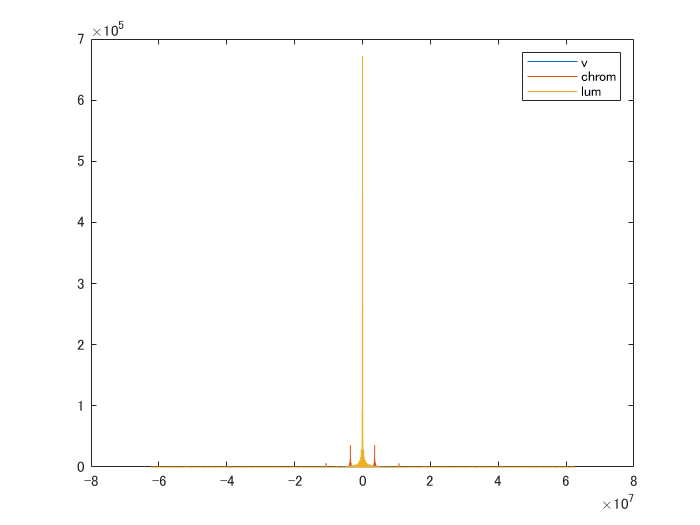

VV = fftshift(fft(v));
ff = linspace(-1/T/2,1/T/2,N)';

combPeriod = 15.734265734265e3;
combHH = -cos(2*pi/combPeriod*ff) /2 + .5;

bandHH = 2*tripuls(ff,2*2e6);
bandHH = -min(bandHH,1) + 1;

chrHH = combHH.*bandHH;
lumHH = 1 - chrHH;

chrVV = chrHH.*VV;
lumVV = lumHH.*VV;

plot(ff,abs([v, chrVV, lumVV]))
legend("v", "chrom", "lum")

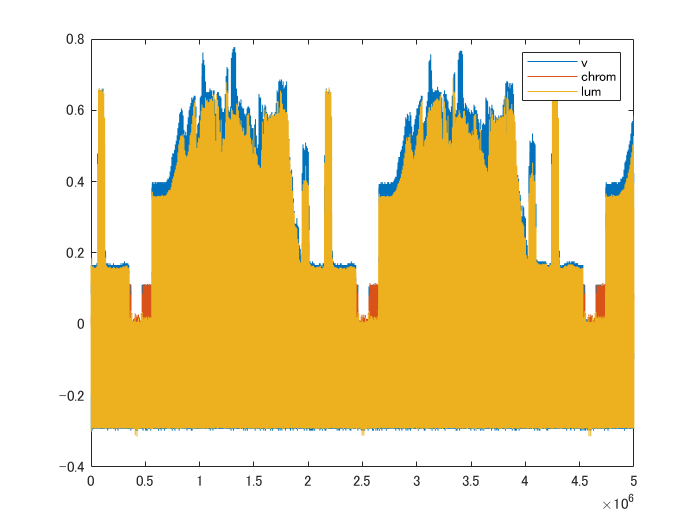


chrv = real(ifft(ifftshift(chrVV)));
lumv = real(ifft(ifftshift(lumVV)));
plot([v, chrv, lumv])
legend("v", "chrom", "lum")